## 0. Initialize Parameters

n = 1251;                   % Number of locations to evaluate bridge failure
L = 1250;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
total_loads = zeros(1, n);  % Initialize total_loads for SFD(x)
ybar = zeros(1, n);         % Initialize section properties: ybar(x) from bottom
I = zeros(1, n);            % I(x)
Q = zeros(1, n);            % Q(x)

## 1. Point Loading Analysis (SFD, BMD)

P = -185; % Change this variable
[SFD_PL, BMD_PL, total_loads] = ApplyPL(550, P, x, total_loads); % Construct load vector
[SFD_PL, BMD_PL, total_loads] = ApplyPL(L, P, x, total_loads); % Construct load vector

## 1.1 Train Load

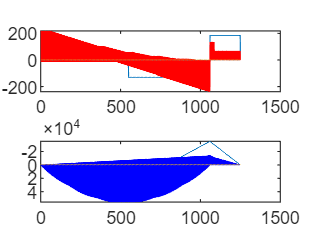

n = 1251;                   % Number of locations to evaluate bridge failure
L = 1250;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
total_loads = zeros(1, n);  % Initialize total_loads for SFD(x)
y_zero = zeros(1,n);        % Initialize y-axis

P = -400;
P_each = P/6;
for n = 52:1250
    x0=n;
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    for i=1:6
        if x_load(i)<=1250
            [SFD_TL, BMD_TL, total_loads] = ApplyPL(x_load(i), P_each, x, total_loads);
        end
    end
subplot(2,1,1);
plot(x, SFD_TL,'red')
plot(x, SFD_PL) % Plot point load SFD on same graph
hold on
subplot(2,1,2);
plot(x, BMD_TL,'blue')
plot(x, BMD_PL) % Plot point load BMD on same graph
set(gca,'YDir','reverse')
hold on
SFD_PL = zeros(1,1251);
BMD_PL = zeros(1,1251);
total_loads = zeros(1,1251);
end

## 2. Define Cross-Sections

% Parameters for left half before drastic change (?)
xc = [0 550 L]; % Location, x, of cross-section change
tfb = [100 100 100]; % Top Flange Width
tft = [2.54 2.54 2.54]; % Top Flange Thickness
wh = [100 120 100]; % Web Height
wt = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
bfb = [80 80 80]; % Bottom Flange Width
bft = [1.27 1.27 1.27]; % Bottom Flange Thickness
a = [400 400 400]; % Diaphragm Spacing

% Optional but you need to ensure that your geometric inputs are correctly implemented
% VisualizeBridge( {CrossSectionInputs} ); 

## 3. Define Material Properties

SigT = 30;  % Tensile strength
SigC = 6;   % Compressive strength
E = 4000;
TauU = 4;   % Shear strength, matboard
TauG = 2;   % Shear strength, glue
mu = 0.2;   % Poisson's ratio

## Function Definitions

function [ SFD_PL, BMD_PL, total_loads ] = ApplyPL( xP, P, x, total_loads )
% Constructs load vector from application of total point loads, then SFD & BMD from total loads.
% Assumes fixed location of supports.
% Input: location and magnitude of point load. The previous load vector can be entered as input to 
% construct the load vector of multiple point loads.
% Output: SFD_PL, BMD_PL, total_loads: 1-D arrays of length n
% xP = distance from left (A) support (x = 0)
xP_B = 1060;
cur_P_B = -P * xP / xP_B; % P_B due to current P
P_A = total_loads(1) -P - cur_P_B; % Overall P_A
P_B = cur_P_B + total_loads(xP_B+1); % Overall P_B

total_loads(1) = P_A;
total_loads(xP+1) = P;
if xP == xP_B
   total_loads(xP_B+1) = P_B + P;
else
    total_loads(xP_B+1) = P_B;
end

% Constructs SFD, BMD from all point loads applied.
n = 1251;
SFD_PL = zeros(1, n);
SFD_PL(1) = total_loads(1);
    for i = 2:length(total_loads)
        SFD_PL(i) = total_loads(i) + SFD_PL(i-1);
    end
    BMD_PL = cumsum(SFD_PL);
end

function [ ybar, I, Q ] = SectionProperties ( xc, tfb, tft, wh, wt, bfb, bft, a )
% Calculates important sectional properties for left half . Including but not limited to ybar, I, Q, etc.
% Input: Geometric Inputs. Format will depend on user
% Output: Sectional Properties at every value of x. Each property is a 1-D array of length n
n = 1251;
x = linspace(0, L, n); % Is this necessary?
% tfb = interp1(xc, tfb, x); % Linearly interpolate remaining points over x
% bfb = interp1(xc, bfb, x);
wh = interp1(xc, wh, x);
ovheight = tft + wh + bft;

% Initialize A, y, I
tfa = zeros(1, n); % Might have to be (n, 1)?
bfa = zeros(1, n);
wa = zeros(1, n);
tfy = zeros(1, n);
bfy = zeros(1, n);
wy = zeros(1, n);
tfi = zeros(1, n);

for i = 1:length(xc)
    % Areas, A
    tfa(i) = tfb(i) * tft(i); % Assumes all values have been interpolated already
    bfa(i) = bfb(i) * bft(i); % If thickness remains constant, use # instead of vector
    wa(i) = 2 * wh(i) * wt(i); % Assumes 2 webs
    
    % Local centroids, y
    tfy(i) = ovheight - tft(i) / 2;
    bfy = bft(i) / 2;
    wy(i) = wh(i)/2 + bft(i);
    
    % I naught, I_0
    tfi(i) = (tfw(i) * (tft(i) ^ 3)) / 12;
    bfi(i) = (bfw(i) * (bft(i) ^ 3)) / 12;
    wi(i) = 2 * (wt(i) * (wh(i) ^ 3)) / 12;

end
ybar = (tfa*tfw + bfa*bfy + wa*wy) / (tfa + bfa + wa);
I = 0;
end